## Тест 0

a = -1;
b = 1;
alpha = [1 1];
beta = [0 1];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = 2/(2+x);
q(x) = cos(x/2);
f(x) = 1+x/2;
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = \frac{2\,\frac{\partial }{\partial x}u\left(x\right)}{{\left(x+2\right)}^{2}}+\cos\left(\frac{x}{2}\right)\,u\left(x\right)-\frac{2\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)}{x+2}=\frac{x}{2}+1$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = u\left(-1\right)-\left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=-1}\right)=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = \left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=1}\right)=0$$

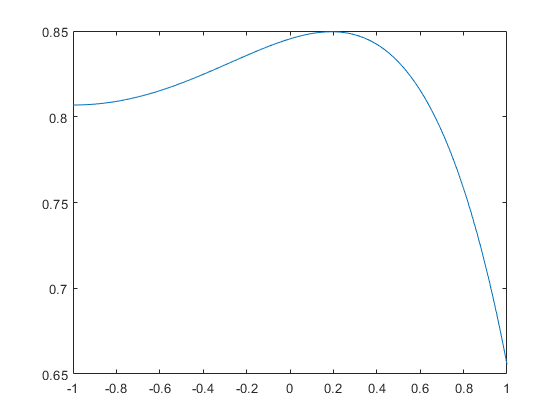

 dp = diff(p);
 fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
 bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
 xmesh = linspace(-1, 1, 100);
 solinit = bvpinit(xmesh, [0 1]);
 sol = bvp4c(fun, bc, solinit);
 plot(sol.x,sol.y(1,:));%grafik tochnogo resheniya

Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = -0.07397\,x^{3}-0.06326\,x^{2}+0.4051\,x+0.7218$$

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = -0.02079\,x^{5}-0.05728\,x^{4}-0.1623\,x^{3}-0.2784\,x^{2}+0.1831\,x+0.3357$$

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Графики полученных решений (методами Ритца и коллок.):

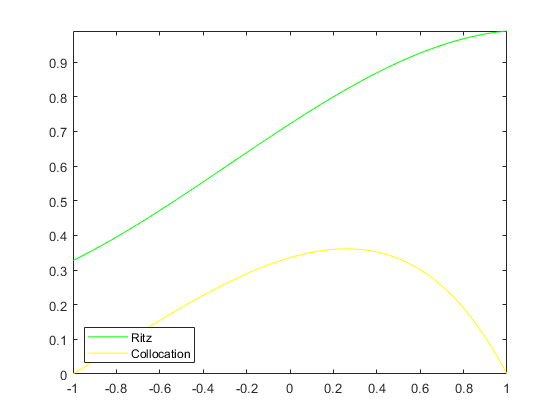

fplot(y_1, [a,b],'g');
hold on;
fplot(y_2, [a,b],'y');
legend({'Ritz','Collocation'},'Location','southwest')
hold off;

Максимальная погрешность:

disp("Максимальная погрешность м.Ритца");

Максимальная погрешность м.Ритца


disp(max(abs(d_1)));

    0.4794



disp("Максимальная погрешность м.коллок.");

Максимальная погрешность м.коллок.


disp(max(abs(d_2)));

    0.8068



Графики погрешностей:

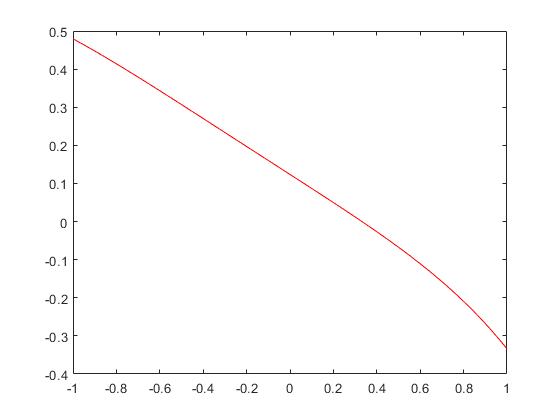

plot(sol.x,d_1,'r')

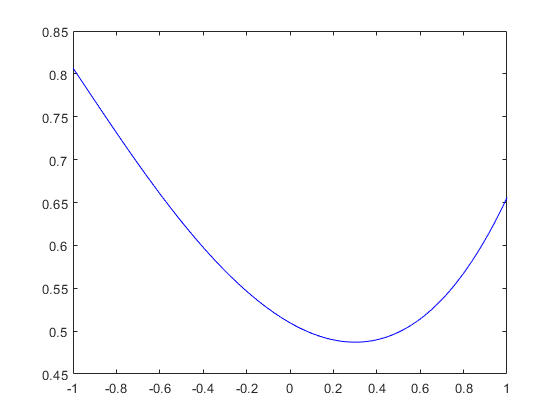

plot(sol.x,d_2,'b')

## Тест 1

a = -1;
b = 1;
alpha = [1 0];
beta = [1 0];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = x.*sin(x);
q(x) = cos(x);
f(x) = log(2+x)-(3*x.^2+7*x+(2*x+4).*log(x+2))./((x+2).^2);
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = \cos\left(x\right)\,u\left(x\right)-\sin\left(x\right)\,\frac{\partial }{\partial x}u\left(x\right)-x\,\sin\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)-x\,\cos\left(x\right)\,\frac{\partial }{\partial x}u\left(x\right)=\log\left(x+2\right)-\frac{7\,x+3\,x^{2}+\log\left(x+2\right)\,\left(2\,x+4\right)}{{\left(x+2\right)}^{2}}$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = u\left(-1\right)=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = u\left(1\right)=0$$

%  dp = diff(p);
%  fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
%  bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
%  xmesh = linspace(-1, 1, 100);
%  solinit = bvpinit(xmesh, [0 1]);
%  sol = bvp4c(fun, bc, solinit);

Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = 0.952\,x^{3}+0.2036\,x^{2}-2.356\,x+0.486$$

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = -0.7344\,x^{5}-0.1015\,x^{4}+2.116\,x^{3}-0.01962\,x^{2}-1.381\,x+0.1211$$

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Графики полученных решений (методами Ритца и коллок.):

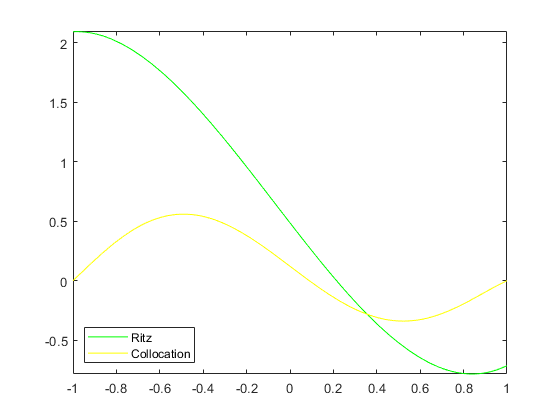

fplot(y_1, [a,b],'g');
hold on;
fplot(y_2, [a,b],'y');
legend({'Ritz','Collocation'},'Location','southwest')
hold off;

Максимальная погрешность:

disp("Максимальная погрешность м.Ритца");

Максимальная погрешность м.Ритца


disp(max(abs(d_1)));

    1.5421



disp("Максимальная погрешность м.коллок.");

Максимальная погрешность м.коллок.


disp(max(abs(d_2)));

    1.1713



Графики погрешностей:

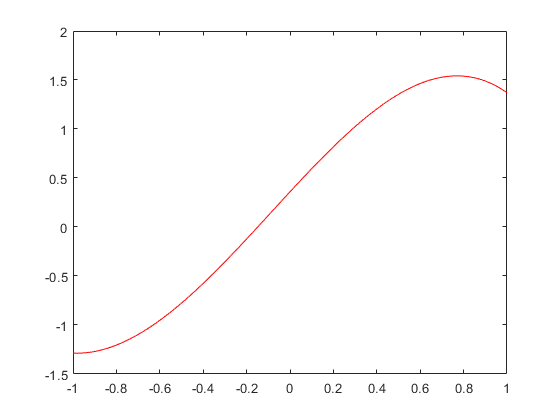

plot(sol.x,d_1,'r')

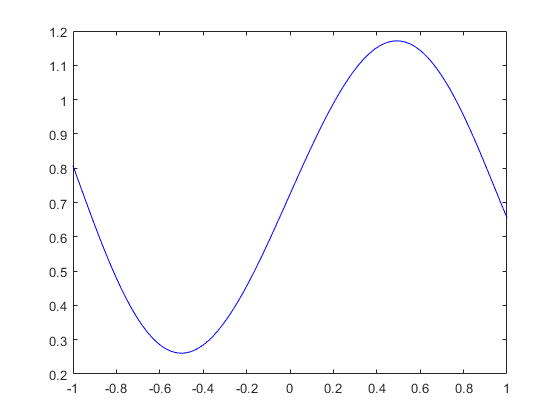

plot(sol.x,d_2,'b')

## Тест 2

a = -1;
b = 1;
alpha = [0 1];
beta = [1 0];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = exp(x.^2).*(x-5)./(x+4);
q(x) = (x.^3-1).*sin(x);
f(x) = x.^3-x.^2.*sin(x)+x;
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = \sin\left(x\right)\,u\left(x\right)\,\left(x^{3}-1\right)-\frac{{\mathrm{e}}^{x^{2}}\,\frac{\partial }{\partial x}u\left(x\right)}{x+4}+\frac{{\mathrm{e}}^{x^{2}}\,\left(x-5\right)\,\frac{\partial }{\partial x}u\left(x\right)}{{\left(x+4\right)}^{2}}-\frac{{\mathrm{e}}^{x^{2}}\,\left(x-5\right)\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)}{x+4}-\frac{2\,x\,{\mathrm{e}}^{x^{2}}\,\left(x-5\right)\,\frac{\partial }{\partial x}u\left(x\right)}{x+4}=x-x^{2}\,\sin\left(x\right)+x^{3}$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = -\left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=-1}\right)=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = u\left(1\right)=0$$

%  dp = diff(p);
%  fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
%  bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
%  xmesh = linspace(-1, 1, 100);
%  solinit = bvpinit(xmesh, [0 1]);
%  sol = bvp4c(fun, bc, solinit);

Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = 0.09955\,x^{3}-0.02037\,x^{2}-0.2796\,x-0.3615$$

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = -0.04304\,x^{5}+0.0145\,x^{4}+0.1523\,x^{3}-0.004755\,x^{2}-0.1093\,x-0.00974$$

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Графики полученных решений (методами Ритца и коллок.):

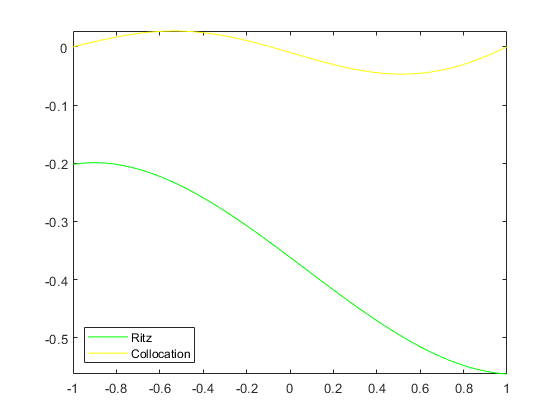

fplot(y_1, [a,b],'g');
hold on;
fplot(y_2, [a,b],'y');
legend({'Ritz','Collocation'},'Location','southwest')
hold off;

Максимальная погрешность:

disp("Максимальная погрешность м.Ритца");

Максимальная погрешность м.Ритца


disp(max(abs(d_1)));

    1.3305



disp("Максимальная погрешность м.коллок.");

Максимальная погрешность м.коллок.


disp(max(abs(d_2)));

    0.8876



Графики погрешностей:

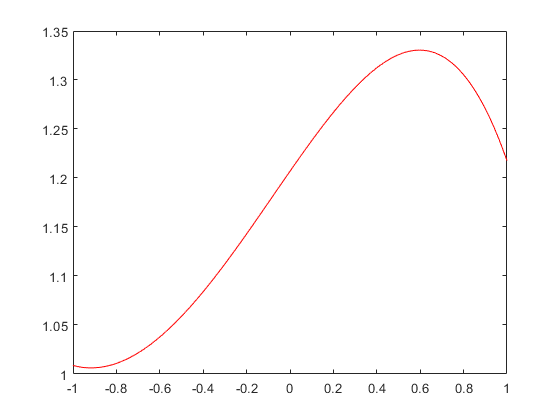

plot(sol.x,d_1,'r')

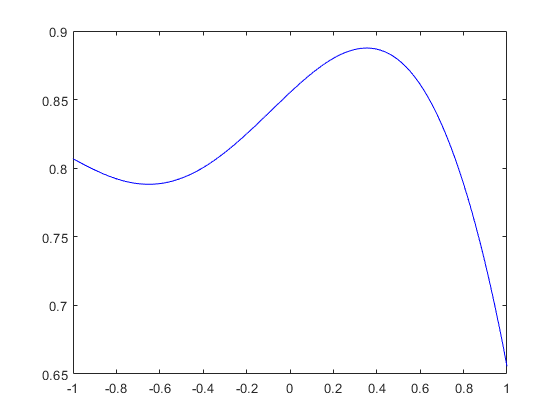

plot(sol.x,d_2,'b')

## **Тест3**

a = 0;
b = 1;
alpha = [1 -1];
beta = [1 1];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = x./((x.^2+1).^2);
q(x) = exp(-x)./((x+1).^(3/2));
f(x) = log(x.^2+1)./(x.^2+1);
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = \begin{array}{l} \frac{4\,x^{2}\,\frac{\partial }{\partial x}u\left(x\right)}{{\left(x^{2}+1\right)}^{3}}-\frac{\frac{\partial }{\partial x}u\left(x\right)}{\sigma_{1}}-\frac{x\,\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)}{\sigma_{1}}+\frac{{\mathrm{e}}^{-x}\,u\left(x\right)}{{\left(x+1\right)}^{3/2}}=\frac{\log\left(x^{2}+1\right)}{x^{2}+1}\\ \mathrm{where}\\ \sigma_{1}={\left(x^{2}+1\right)}^{2} \end{array}$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = u\left(0\right)+\left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=0}\right)=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = u\left(1\right)+\left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=1}\right)=0$$

%  dp = diff(p);
%  fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
%  bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
%  xmesh = linspace(-1, 1, 100);
%  solinit = bvpinit(xmesh, [0 1]);
%  sol = bvp4c(fun, bc, solinit);

Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = -0.2288\,x^{3}+0.1485\,x^{2}+0.147\,x+0.2091$$

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = -0.05933\,x^{5}-0.04138\,x^{4}-0.02616\,x^{3}-0.04263\,x^{2}+0.0855\,x+0.08401$$

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Графики полученных решений (методами Ритца и коллок.):

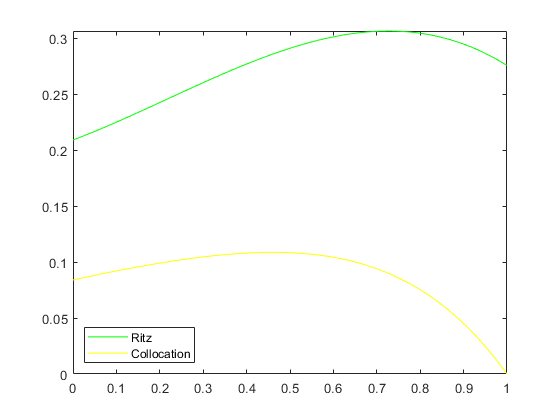

fplot(y_1, [a,b],'g');
hold on;
fplot(y_2, [a,b],'y');
legend({'Ritz','Collocation'},'Location','southwest')
hold off;

Максимальная погрешность:

disp("Максимальная погрешность м.Ритца");

Максимальная погрешность м.Ритца


disp(max(abs(d_1)));

    0.6483



disp("Максимальная погрешность м.коллок.");

Максимальная погрешность м.коллок.


disp(max(abs(d_2)));

    0.8081



Графики погрешностей:

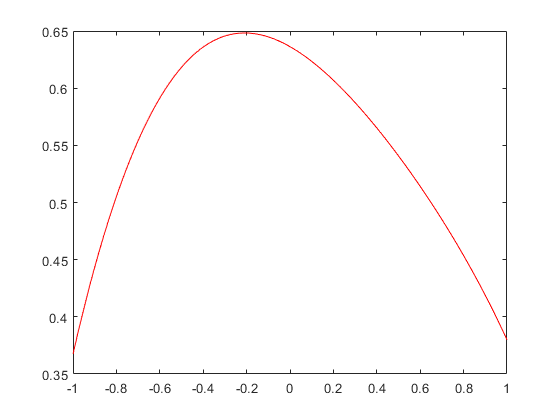

plot(sol.x,d_1,'r')

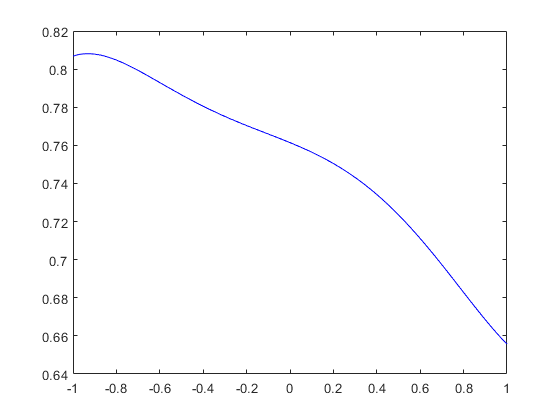

plot(sol.x,d_2,'b')

## Тест4 

% a = -1;
% b = 1;
% alpha = [1 -1];
% beta = [0 1];
% syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
% p(x) = 2/(2+x);
% q(x) = cos(x/2);
% f(x) = 1+x/2;
% v(x) = vpa(0);
% n = 4;
% Du = diff(u);

Решаем следующий дифур:

% -diff(p*diff(u)) +v*diff(u)+q*u == f

Краевые условия:

% alpha(1)*u(a)-alpha(2)*Du(a) == 0
% beta(1)*u(b)+beta(2)*Du(b) == 0

Точное решение:

% % dp = diff(p);
% % fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
% % bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
% % xmesh = linspace(-1, 1, 100);
% % solinit = bvpinit(xmesh, [0 1]);
% % sol = bvp4c(fun, bc, solinit);
% % plot(sol.x,sol.y(1,:));

 Численное решение методом Ритца:

% y_1= ritz(a,b,alpha,beta, n, p, q, f);
% y_1 = simplify(y_1)
% d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Численное решение методом коллакаций:

% y_2 = coloc(a,b,n, p, q, f, v);
% y_2 = simplify(y_2)
% d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Графики полученных решений (методами Ритца и коллок.):

% fplot(y_1, [a,b],'g');
% hold on;
% fplot(y_2, [a,b],'y');
% legend({'Ritz','Collocation'},'Location','southwest')
% hold off;

Максимальная погрешность:

% disp("Максимальная погрешность м.Ритца");
% disp(max(abs(d_1)));
% disp("Максимальная погрешность м.коллок.");
% disp(max(abs(d_2)));

Графики погрешностей:

% tiledlayout(2,2)
% nexttile
% plot(sol.x,d_1,'r')
% nexttile
% plot(sol.x,d_2,'b')

## Тест5 

a = 1;
b = 5;
alpha = [0.1 0.01];
beta = [1 1/2];
syms 'p(x)' 'q(x)' 'f(x)' 'x' 'v(x)' 'u(x)';
p(x) = 1/(1+x);
q(x) = exp(x);
f(x) = (3*x.^2-6*x-1)./((x+1).^2)+(x.^3+x+2).*exp(x);
v(x) = vpa(0);
n = 4;
Du = diff(u);

Решаем следующий дифур:

-diff(p*diff(u)) +v*diff(u)+q*u == f

$$ans(x) = {\mathrm{e}}^{x}\,u\left(x\right)+\frac{\frac{\partial }{\partial x}u\left(x\right)}{{\left(x+1\right)}^{2}}-\frac{\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)}{x+1}={\mathrm{e}}^{x}\,\left(x^{3}+x+2\right)-\frac{-3\,x^{2}+6\,x+1}{{\left(x+1\right)}^{2}}$$

Краевые условия:

alpha(1)*u(a)-alpha(2)*Du(a) == 0

$$ans = \frac{u\left(1\right)}{10}-\frac{{\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=1}}{100}=0$$

beta(1)*u(b)+beta(2)*Du(b) == 0

$$ans = u\left(5\right)+\frac{{\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=5}}{2}=0$$

%  dp = diff(p);
%  fun = @(x,y) [y(2); -(((dp(x)-v(x))/p(x))*y(2)-(q(x)/p(x))*y(1)+f(x)/p(x))];
%  bc = @(ya, yb) [ya(2); yb(2)+yb(1)];
%  xmesh = linspace(-1, 1, 100);
%  solinit = bvpinit(xmesh, [0 1]);
%  sol = bvp4c(fun, bc, solinit);

 Численное решение методом Ритца:

y_1= ritz(a,b,alpha,beta, n, p, q, f);
y_1 = simplify(y_1)

$$y\_1 = 0.7774\,x^{3}+1.377\,x^{2}-0.3088\,x-0.05426$$

d_1 = sol.y(1,:) - double(subs(y_1,'x',sol.x));

Численное решение методом коллакаций:

y_2 = coloc(a,b,n, p, q, f, v);
y_2 = simplify(y_2)

$$y\_2 = -0.2939\,x^{5}+3.347\,x^{4}-11.29\,x^{3}+13.01\,x^{2}+11.58\,x-16.36$$

d_2 = sol.y(1,:) - double(subs(y_2,'x',sol.x));

Графики полученных решений (методами Ритца и коллок.):

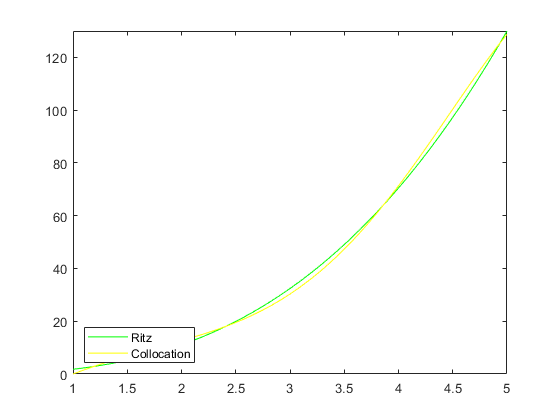

fplot(y_1, [a,b],'g');
hold on;
fplot(y_2, [a,b],'y');
legend({'Ritz','Collocation'},'Location','southwest')
hold off;

Максимальная погрешность:

disp("Максимальная погрешность м.Ритца");

Максимальная погрешность м.Ритца


disp(max(abs(d_1)));

    1.1360



disp("Максимальная погрешность м.коллок.");

Максимальная погрешность м.коллок.


disp(max(abs(d_2)));

   19.1581



Графики погрешностей:

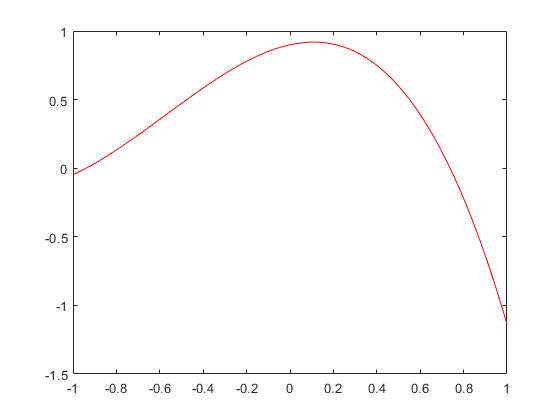

plot(sol.x,d_1,'r')

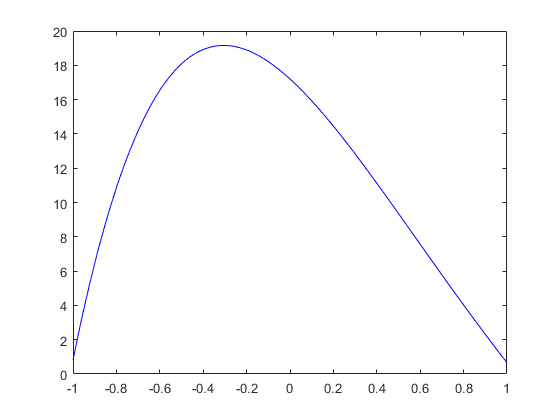

plot(sol.x,d_2,'b')